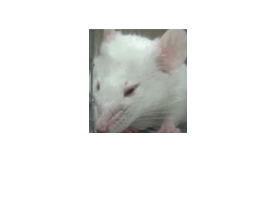

clc; clear; close all

img=imread('Test_rat_image3.png'); % Insert image of here
imshow(img)

I=rgb2gray(img);


[I_test, threshold]=edge(I,'Canny');

Threshold 

threshold;
% adjust threshold till there is no error or eye is isolated
I_edge=edge(I,'Canny',4.2* threshold); 

Eye isolation

se90=strel('line',3,90);
se0=strel('line',3,0);
I_dilate=imdilate(I_edge,[se90 se0]);

I_fill=imfill(I_dilate,'holes');

I_erode=imerode(I_fill,[se90 se0]);
I_erode=imerode(I_erode,[se90 se0]);
I_clear=imclearborder(I_erode);

I_final=labeloverlay(img,I_clear);

Final images

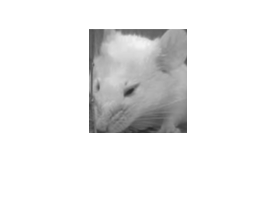

imshow(I)

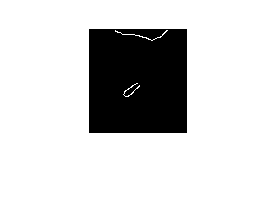

imshow(I_edge)

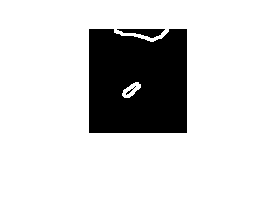

imshow(I_dilate)

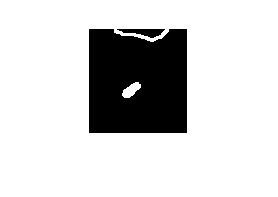

imshow(I_fill)

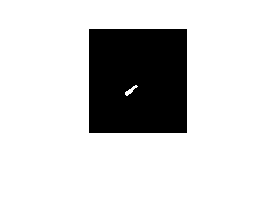

imshow(I_erode)

imshow(I_clear)

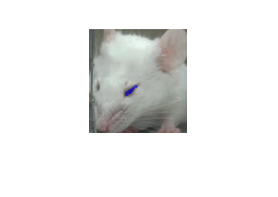

imshow(I_final)

Attaining eye data 


region=regionprops(I_clear,'Area','Centroid','orientation','MajoraxisLength','MinoraxisLength','BoundingBox')

region = struct with fields:
               Area: 52
           Centroid: [42.2692 62.1346]
        BoundingBox: [36.5000 56.5000 13 11]
    MajorAxisLength: 16.6913
    MinorAxisLength: 4.4207
        Orientation: 39.3778


Area=[region.Area];
eye_target=find(Area==max(Area));

% field that contains biggest area
eye_data=region(eye_target);

% we want to evaluate the image of the best/biggest eye
bigeye_Area=Area(eye_target) ;

BoundingBox=eye_data.BoundingBox;

X_dimension=BoundingBox(3);
Y_dimension=BoundingBox(4);

XY_ratio= Y_dimension/X_dimension;;

MajorAxis=eye_data.MajorAxisLength

MajorAxis = 16.6913

MinorAxis=eye_data.MinorAxisLength

MinorAxis = 4.4207


Major_Minor_Ratio=MinorAxis/MajorAxis

Major_Minor_Ratio = 0.2648


% Value for the ratio differentiation was determine in Rat_LDA_Analysis code
if Major_Minor_Ratio>=.4824 
    fprintf('The rat is not in pain')
else
    fprintf('the rat is in pain')
end

the rat is in pain